# Perceptron Example

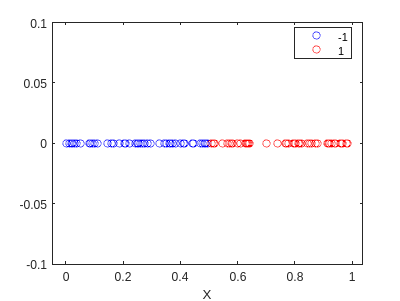

rng(5)
X = rand([100,1]);
y = 2*(double(X>0.5)-0.5*ones(size(X)));

f=gscatter(X,zeros(size(X)),y,'br','o');
hold on
ylim([-0.1,0.1])
hold off

Now, let's manually use our perceptron:

W = [-0.5; 1]

W =    -0.5000
    1.0000



% Add the bias
X_bias = [ones(size(X)) X];

pred = zeros(size(X));

for i=1:length(X)
    x = X_bias(i,:)';
    S = state(x,W);
    pred(i) = my_sign(S);
end

f2=gscatter(X,zeros(size(X)),pred,'br','o');
hold on
ylim([-0.1,0.1])
hold off

It classified perfectly! Now let's train the algorithm:

% Add the bias
X_bias = [ones(size(X)) X];

% Train the model
W2 = train(X_bias,y,0.1,10)

W2 =    -0.1000
    0.2013


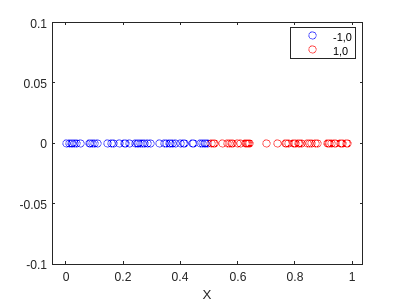


pred2 = zeros(size(X_bias));

for i=1:length(X)
    x = X_bias(i,:)';
    S = state(x,W2);
    pred2(i) = my_sign(S);
end

f3=gscatter(X,zeros(size(X)),pred2,'br','o');
hold on
ylim([-0.1,0.1])
hold off

This is quite interesting... it found different weights, but it classified eveything well. This must break somewhere. Let's try to determine where:

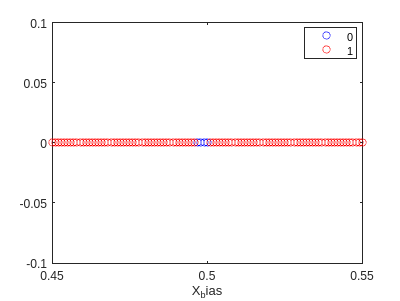

X = 0.45:0.001:0.55;
X = X';
y = 2*(double(X>0.5)-0.5*ones(size(X)));

X_bias = [ones(size(X)) X];

pred3 = zeros(size(X));

for i=1:length(X)
    x = X_bias(i,:)';
    S = state(x,W2);
    pred3(i) = my_sign(S);
end

f4=gscatter(X_bias,zeros(size(X)),pred3==y,'br','o');
hold on
ylim([-0.1,0.1])
xlim([0.45,0.55])
hold off


y(pred3~=y)

ans =     -1
    -1
    -1
    -1


This means that our model is actually setting the bound a little bit before 0.5 (as can be seen in the graph). This should be improved by increasing the size of X.

function S = state(X, W)
    S = W'*X;
end

function pred = my_sign(S)
    if S > 0
        pred = 1;
    else
        pred = -1;
    end
end

function W = train(X, y, lr, epochs)
    [~, d] = size(X);
    W = zeros(d, 1);
    for epoch = 1:epochs
        for i = 1:length(X)
            x = X(i,:)';
            pred = my_sign(state(x, W));
            if pred ~= y(i)
                W = W + lr*x*y(i);
            end
        end
    end
end
